# 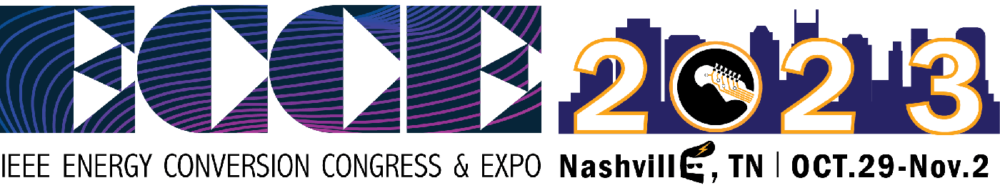

# Artificial Neural Network for Power Electronics 

*Faete "JT" Filho, Savannah River National Laboratory, USA*

*Raymundo Cordero, Associate Professor, Federal University of Mato Grosso do Sul, Brazil*

*                                                                                                           -*

**Task 1: **The goal is to use an Artificial Neural Network to calculate the firing angle for Selective Harmonic Minimization for Cascaded Multilevel Inverters with varying DC sources.

# 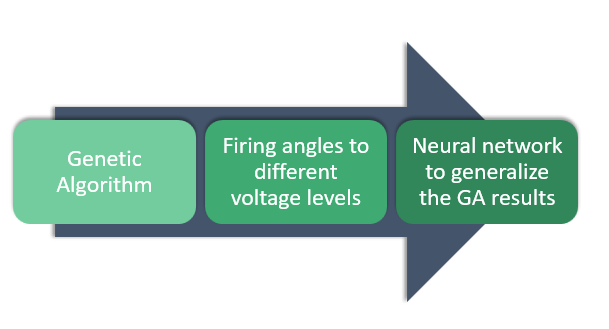

Figure 1: Neural newtork pre-processing.

**1º step: **Load the data to train the Neural Network

clear variables
load data_ann; %training data
rng = 100; %to make sure we all will train the same neural network.

In this problem, the inputs are 1,922 samples of 2 voltages levels. The outputs are 6 switching angles for each one of the voltage combinations, generated by the Genetic Algorithm. 

Six angles mean that we can control the fundamental and five harmonics (3rd, 5th, 7th, 9th, and 11th).

**2º step: **Neural Network configuration

The following code opens the Matlab Neural Network Fitting app interface.

nftool; % training system

*Using the interface, you can train a two-layer feed-forward network with ****sigmoid**** hidden neurons and linear output. The network will be trained with your choice between ****Levenberg-Marquardt*** ***backpropagation, Bayesian Regularization or*** ***Scaled Conjugate*** ***Gradient**** algorithms. For this particular problem, a two-layer neural network will be enough for a good generalization. To customize the neural network characteristics and training, command-line coding can be used.* See Matlab [documentation](https://www.mathworks.com/help/deeplearning/gs/fit-data-with-a-neural-network.html).

**3º step: **With the NN Fitting tool open, click on *Import*. Under *Predictors*, select *inputs, and as Responses, select* *outputs. *In the field Observations in, select C*olumns*, since we have 1,922 samples of 2 elements (voltages) and the outputs are 1,922 samples of the 6 switching angles. Click on *OK*.

**4º step: **In order to ensure that the model generalizes well to unseen data, the data (input and outputs) must be split into training, validation, and test. We will use the default option (70% training, 15% validation and 15% test).

**5º step: **A two layer Neural Network is being trained in this demo. In this step, the number of neurons in the hidden layer can be changed. For this problem, 8 neurons will be used. Go ahead and type **8** in the field *Layer size.*

**6º step: **As *training algorithm*, choose Levenberg-Marquardt and click on *Train*.

**7º step: **Now, lets save the neural network in *Export Model*: 

- Click on Export Network Function for Matlab Compiler. Save the file with the name "ann8". We will use this file to evaluate the outputs and the estimated outputs by the Neural Network later.

- Click on Export to *Simulink*. The Neural Network will be created in the Simulink environment and will be used later. Do not close the file.

**8º step**: Before moving to the Simulink model, lets analyze the neural network performance by comparing its output with the target values:

% Simulation of the ANN
estimated = ann8(inputs);

% Represents each input combination
index = 1:1922;

figure(1)
% Plotting angles
for i = 1:6
    subplot(2,3,i); 
    plot(index, outputs(i,:), 'r', index, estimated(i,:), 'b'); 
    grid on; 
    ylabel(['angle ', num2str(i)]); 
    legend('Desired','Estimated', 'location', 'NorthWest')
end

% Outcome of training files
figure(2)
for i = 1:6
    subplot(2,3,i); 
    plot(error(i,:), 'r'); 
    grid on; 
    ylabel(['Error for angle ', num2str(i)]); 
    legend(['Angle ', num2str(i)], 'location', 'best')
end


**9º step**: Now the NN is trained and in good shape, move to the Simulink model.

open('ECCE_demo1_model')

Copy the neural network  created on step 7 and paste it in the Simulink model, in the marked area. As expected, the inputs of the neural network are the voltage levels, which will change during the simulation, and the outputs are the 6 angles that are fed in the control logic.

**10º step**: Now, simulate the model with 10 cycles. Click on the *Run* button. 

**11º step**: Double-click the grey button under the output voltage scope to open the FFT analysis. In the field *FFT settings*, go to *Number of cycles* and enter 10. Under *max frequency*, use 2000. In *frequency axis*, choose *Harmonic order*. Finally, click on the *Compute FFT*.

Even with the voltage change that occurred in a 0.1-second interval, it's evident that the 3rd, 5th, 7th, 9th, and 11th harmonics are significantly reduced compared to other harmonic orders.

**Instructor Team:**

Joao O. P. Pinto – Chair Oak Ridge National Laboratory – Knoxville 

Burak Ozpineci – Co-Chair Oak Ridge National Laboratory – Knoxville 

Marcio L. M. Kimpara – Co-Chair Oak Ridge National Laboratory – Knoxville

Pedro Eugênio M. Ribeiro - Oak Ridge National Laboratory – Knoxville 

Renata Rezende Reis - Federal University of Mato Grosso do Sul (UFMS) - Brazil

Feel free to contact us at [pintoj@ornl.gov](mailto:pintoj@ornl.gov) 